# Fault Detection of Electric Vehicle Charger

## Open EV Charger Model

Open the model `ee_EVchargerFaultAnalysis`

open_system("ee_EVchargerFaultAnalysis.slx")

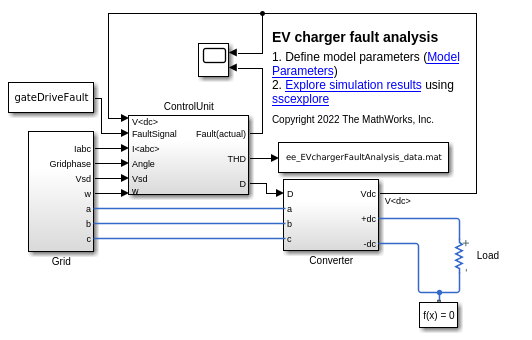

The model comprises three major subsystems: Grid, Converter, and ControlUnit. The resistor block, Load, represents the system load. In this example, you simulate the fault of gate drivers for one or more IGBT duty cycles. No other fault is considered. The gateDriveFault block defines a fault in the gate driver operation. The input to the Converter subsystem is a column vector of six elements, which represent the six IGBTs. Each element is either 0 (no fault) or 1 (fault). You can simulate uncertainties in system by setting the Resistance parameter of the Load block to different values. The `ee_EVchargerFaultAnalysis_data` MAT file stores the measured total harmonic distortion (THD) on the AC grid side. 

The Grid subsystem is modeled as an ideal voltage source. To model a grid with a different grid voltage and frequency, change the parameters in the `ee_EVchargerFaultAnalysis_ini` file.

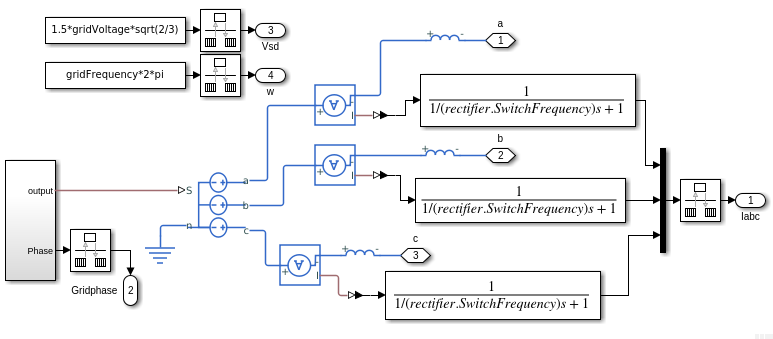

The Converter subsystem is modeled as a three-phase, two-level converter using IGBT (Ideal, Switching) blocks. You can fault any of the six IGBTs by changing the duty cycle, D, to zero. To change the duty cycle, use the **gateDriveFault** parameter.

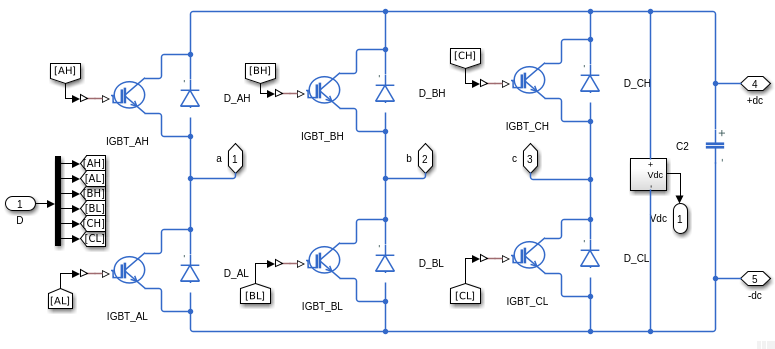

The ControlUnit subsystem controls the three-phase converter by using id-iq control, with unity power-factor operation, that enables a constant DC voltage of 800V. 

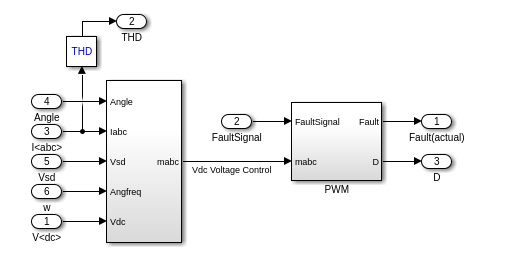

## Generating Training Data

% Grid data
gridVoltOptions = 415;         % V,   Line-Line rms voltage
loadOptions = [8 9 10 11 12];  % Ohm, System load

## Training and Validating Model

trainingData=load("ee_EVchargerFaultAnalysis_trainingData.mat").trainingData;
trainingData.gridDCvolt = [];
trainingData.driverFault = categorical(trainingData.driverFault);
trainingData.driverFault = categorical(trainingData.driverFault,...
    ["0","1","10","11","100","101","110"],"Ordinal",true);
[trainedClassifier, validationAccuracy] = ...
    ee_EVchargerFaultAnalysis_trainClassifier(trainingData)

trainedClassifier = struct with fields:
                predictFcn: @(x)ensemblePredictFcn(predictorExtractionFcn(x))
         RequiredVariables: {'gridTHD_a'  'gridTHD_b'  'gridTHD_c'  'systemLoad'}
    ClassificationEnsemble: [1x1 classreg.learning.classif.ClassificationBaggedEnsemble]
                     About: 'This struct is a trained model exported from Classification Learner R2022a.'
              HowToPredict: 'To make predictions on a new table, T, use: ...'


validationAccuracy = 0.9081

## Verifying Model Predictions

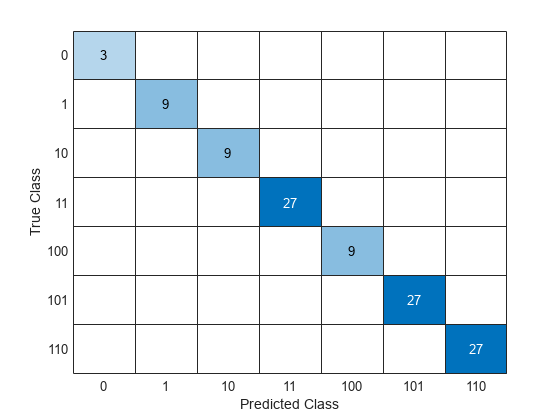

testData=load("ee_EVchargerFaultAnalysis_testData.mat").testData;
testData.gridDCvolt = [];
testData.driverFault = categorical(testData.driverFault);
testData.driverFault = categorical(testData.driverFault,...
    ["0","1","10","11","100","101","110"],"Ordinal",true);
% Predicted labels
pred_fault = trainedClassifier.predictFcn(testData(:,1:4));
% Actual labels
real_fault = testData(:,5);
confusionchart(pred_fault,table2array(real_fault))

The Predicted Class and the True Class match for all the test data points. This shows a very good success rate in identifying the right kind of fault or no fault.

## Generating and Deploying Code

saveLearnerForCoder(trainedClassifier.ClassificationEnsemble,...
    "ee_EVchargerFaultAnalysis_codegen");
% Simulation parameters
systemLoadR=11.2;
gridVoltage=415;
gateDriveFault=[1;0;0;0;0;0]; % Gate Driver for AH faulted (a phase)
realFault_a=min(1,gateDriveFault(1,1)+gateDriveFault(2,1));
realFault_b=min(1,gateDriveFault(3,1)+gateDriveFault(4,1));
realFault_c=min(1,gateDriveFault(5,1)+gateDriveFault(6,1));
%
% Check fault during time sample of 0.25 (= tEnd-tStart) seconds
tStart = 0.2; 
tEnd = 0.45;

thd=load("ee_EVchargerFaultAnalysis_data.mat");
startData=find(thd.THD.Time==tStart);
endData=find(thd.THD.Time==tEnd);

gridTHD_a=thd.THD.Data(startData:endData,1);
gridTHD_b=thd.THD.Data(startData:endData,2);
gridTHD_c=thd.THD.Data(startData:endData,3);
lenData=length(gridTHD_a);
sysLoad=ones(lenData,1)*systemLoadR;
% Measured Data
measData=[sysLoad,gridTHD_a,gridTHD_b,gridTHD_c];
% Predict if there is any fault detected
[predFault_a,predFault_b,predFault_c] = ...
    ee_EVchargerFaultAnalysis_codegenFunc(measData);
%
if isequal(predFault_a,realFault_a) && ...
        isequal(predFault_b,realFault_b) && ...
        isequal(predFault_c,realFault_c)
    disp('*** Prediction : Correct !!')

else
    disp('*** Prediction : Incorrect !!')
end

*** Prediction : Correct !!


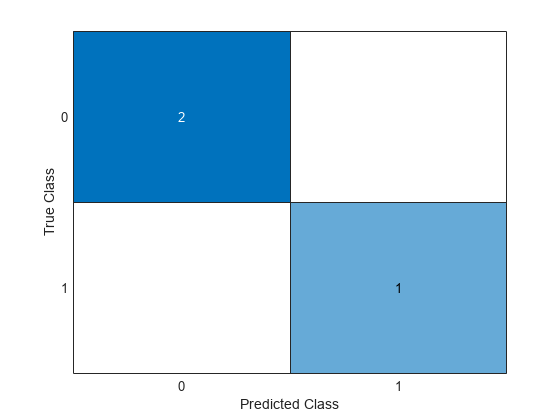

confusionchart(...
    [predFault_a,predFault_b,predFault_c],...
    [realFault_a,realFault_b,realFault_c]);